clear; close all;

Initial coordinates

X = readmatrix('Sample Geometry.xlsx');
X = X(:,2:end)

X =     2.0000         0         0
    1.0000    3.0000         0
         0         0         0
    2.0000         0    2.0000
    0.8000    2.8000    2.2000
         0         0    1.8000
         0         0         0
         0         0         0
         0         0         0
         0         0         0


[A, B, C, D, E, F, G, H, J, K, L, M, N, P, R] = deal(...
    X(1,:), X(2,:), X(3,:), X(4,:), X(5,:),...
    X(6,:), X(7,:), X(8,:), X(9,:), X(10,:),...
    X(11,:), X(12,:), X(13,:), X(14,:), X(15,:) ...
    )

A =      2     0     0


B =      1     3     0


C =      0     0     0


D =      2     0     2


E =     0.8000    2.8000    2.2000


F =          0         0    1.8000


G =      0     0     0


H =      0     0     0


J =      0     0     0


K =      0     0     0


L =      0     0     0


M =     1.5000    3.0000         0


N =     2.5000         0         0


P =      0     0     0


R =      0     0     0


## LCA rotation

Sweep LCA angle

alpha = deg2rad(linspace(-10, 10, 100));
gamma = deg2rad(linspace(-20, 20, 100));

% The layout of d is [Arot, alpha, Erot, beta, Mrot, gamma, deltaN]
d = zeros(length(alpha)*length(gamma), 13);

upright_length = norm(E - B);
tierod_length = norm(M - N)

tierod_length = 3.1623

for i = 1:length(alpha)
    % rotate LCA
    Brot = rotate_A_arm(A, B, C, alpha(i));
    
    % find where UCA should be
    beta = fzero(@(beta) norm(rotate_A_arm(D, E, F, beta) - Brot) - upright_length, alpha(i));
    Erot = rotate_A_arm(D, E, F, beta);
    
    % find where upright would point if steering rack didn't move after
    % bump
    gamma_i = fzero(@(gamma) norm(rotate_A_arm(Brot, M, Erot, gamma) - N) - tierod_length, 0);
    % add desired changes
    gamma_sweep = gamma + gamma_i;
    for j = 1:length(gamma)
        % rotate upright by desired amount
        Mrot = rotate_A_arm(Brot, M, Erot, gamma_sweep(j));
        % find what rack displacement is necessary to rotate the upright
        deltaN = fzero(@(deltaY) norm(Mrot - (N + deltaY*[0 1 0])) - tierod_length, Mrot(2) - M(2));
        % save outputs
        d(i * length(gamma) +j - 1, :) = [Brot, alpha(i), Erot, beta, Mrot, gamma_sweep(j), deltaN];
    end  
end

Plot results

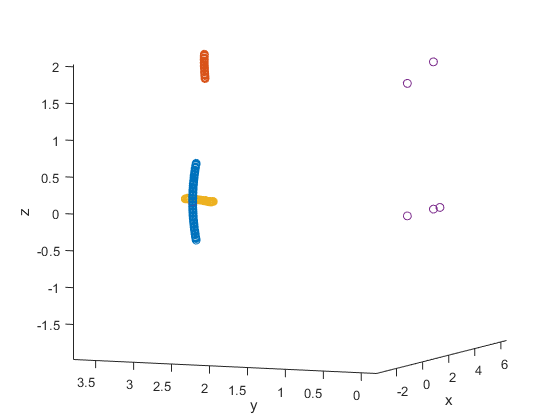

plot3(d(:, 1), d(:,2), d(:,3), 'o', d(:, 5), d(:,6), d(:,7), 'o', d(:,9), d(:,10), d(:,11), 'o')
hold on
plot3(X(:,1), X(:,2), X(:,3), 'o')
hold off
xlim([-5,5])
ylim([0,4])
zlim([-2,2])
xlabel('x')
ylabel('y')
zlabel('z')

Check errors

errors = [vecnorm(d(:,1:3) - A, 2, 2) - norm(B - A);
vecnorm(C - d(:,1:3), 2, 2) - norm(C - B);

vecnorm(D - d(:,5:7), 2, 2) - norm(D - E);
vecnorm(d(:,5:7) - F, 2, 2) - norm(E - F);

vecnorm(d(:,1:3) - d(:,5:7), 2, 2) - norm(B - E)];

max(abs(errors))

ans = 3.1623